# Figure 1 - Compare subjects across conditions

Caption: These six panels show the different measurement conditions.  The columns show data acquired with one of excitation light (405 nm, 415 nm, 450nm).  The upper row show data acquired from the lip and the bottom row from the tongue. The curves in each panel show data from four different subjects, all measured with an excitation light of the same intensity.  The curves have been normalized to match at 580 nm.  

ieInit;
waves = 500:5:700;
T = oeDatabaseCreate;

## Lip 405 (980 mA)

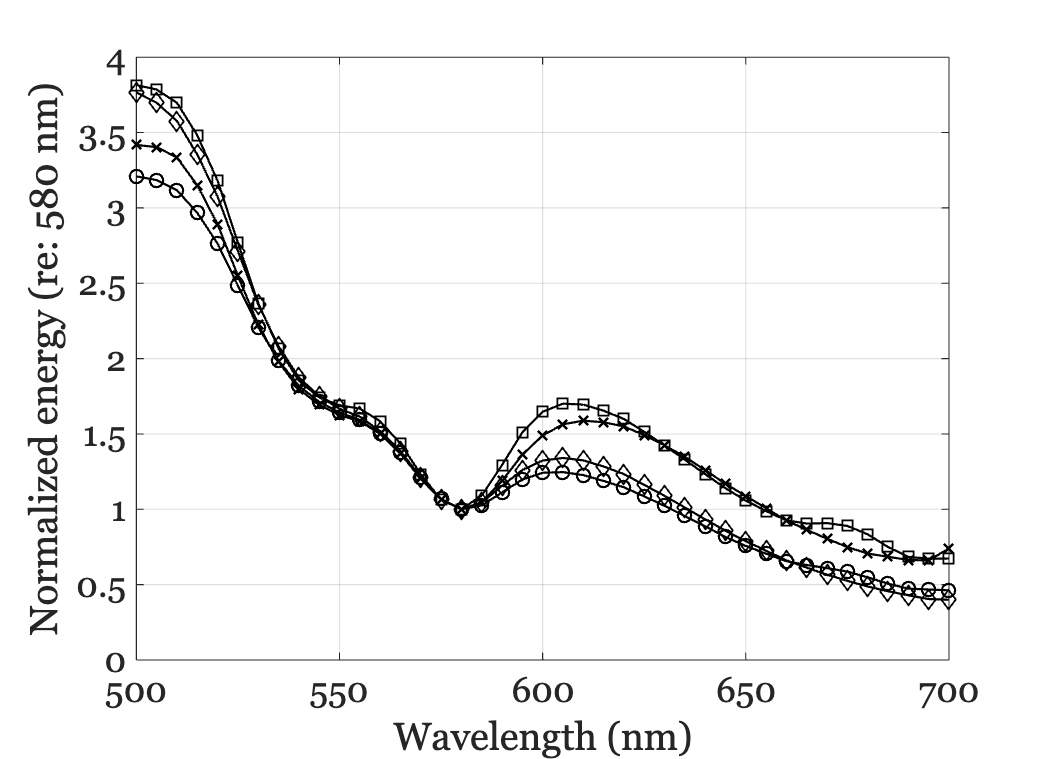

lipFiles405 = ieTableGet(T,'ewave',405,'substrate','lip','elevel',980,'return','files');

idx = find(waves==580);
data = zeros(numel(waves),numel(lipFiles405));
for ii=1:numel(lipFiles405)
    data(:,ii) = ieReadSpectra(lipFiles405(ii),waves);
    data(:,ii) = data(:,ii)/data(idx,ii);
end

symbols = {'ko-','kx-','ks-','kd-'};
ieFigure;
for ii= 1:numel(lipFiles405)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
end
grid on;
xlabel('Wavelength (nm)')
ylabel('Normalized energy (re: 580 nm)');

## Lip 415 (980 mA)

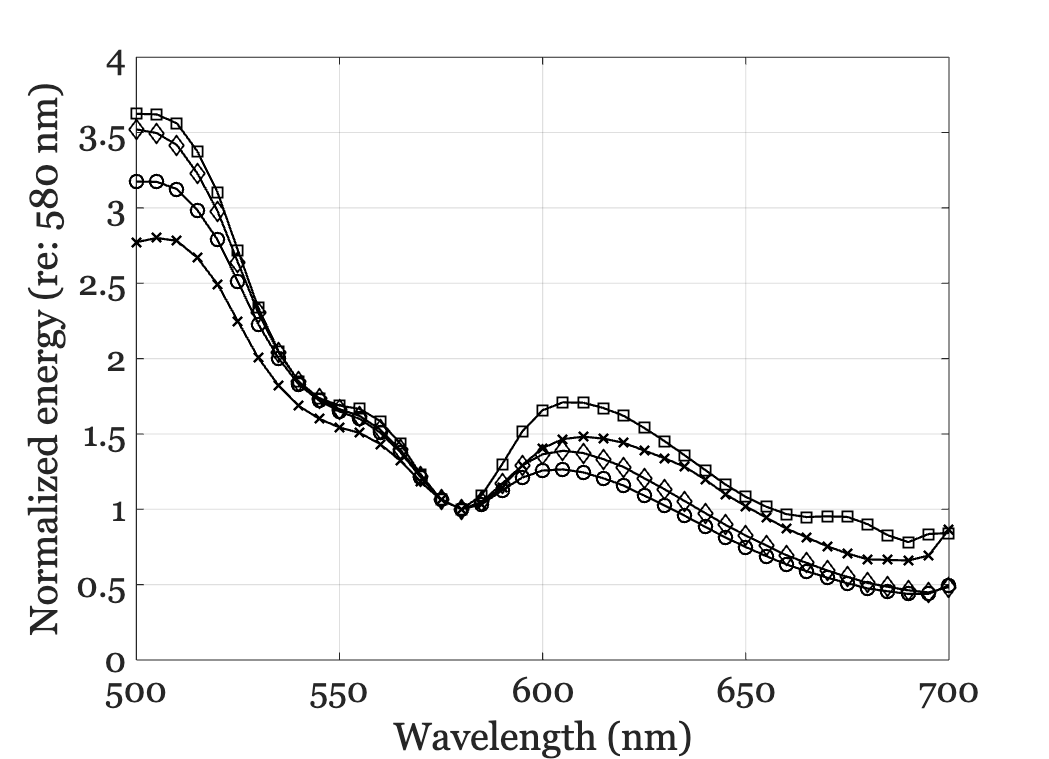

lipFiles415 = ieTableGet(T,'ewave',415,'substrate','lip','elevel',910,'return','files');

idx = find(waves==580);
data = zeros(numel(waves),numel(lipFiles415));
for ii=1:numel(lipFiles415)
    data(:,ii) = ieReadSpectra(lipFiles415(ii),waves);
    data(:,ii) = data(:,ii)/data(idx,ii);
end

% Collected on the same day as above.
selected = [11,12,13,14];
lipFiles415 = lipFiles415(selected);
data = data(:,selected);

symbols = {'ko-','kx-','ks-','kd-'};
ieFigure;
for ii= 1:numel(lipFiles415)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
end
grid on;
xlabel('Wavelength (nm)')
ylabel('Normalized energy (re: 580 nm)');

## Lip 450 (870 mA)

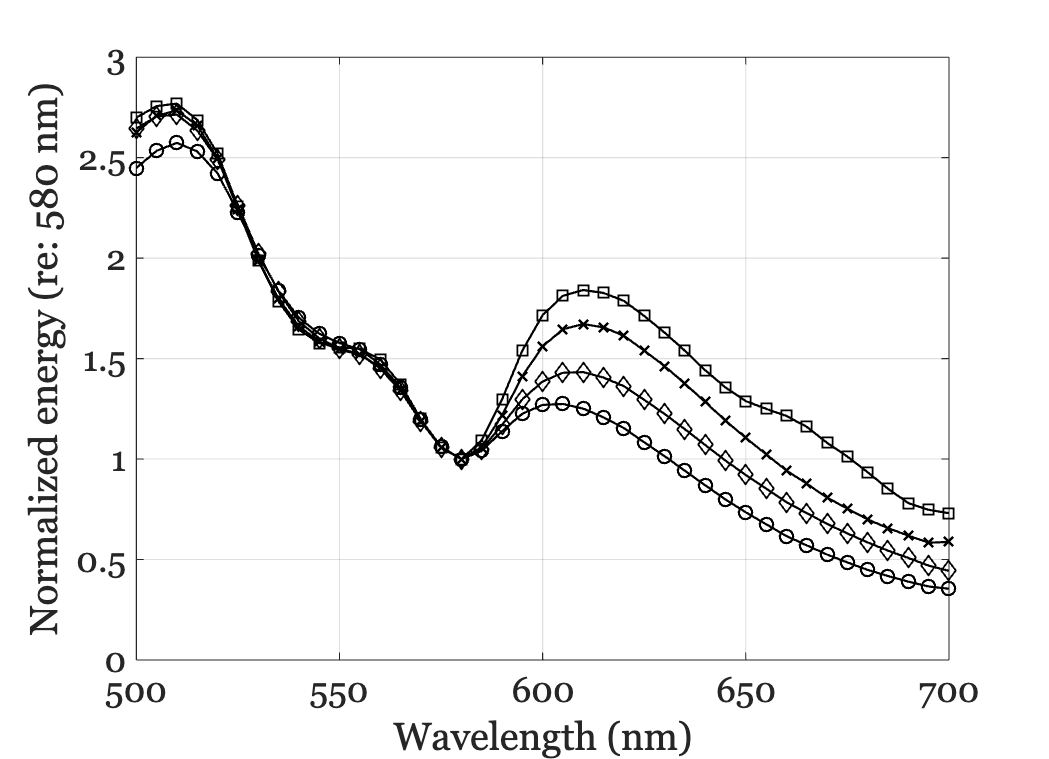

lipFiles450 = ieTableGet(T,'ewave',450,'substrate','lip','elevel',870,'return','files');

data = zeros(numel(waves),numel(lipFiles450));
for ii=1:numel(lipFiles450)
    data(:,ii) = ieReadSpectra(lipFiles450(ii),waves);
    data(:,ii) = data(:,ii)/data(waves==580,ii);
end

% Collected on the same day as above.

symbols = {'ko-','kx-','ks-','kd-'};
ieFigure;
for ii= 1:numel(lipFiles450)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
end
grid on;
xlabel('Wavelength (nm)')
ylabel('Normalized energy (re: 580 nm)');

## Tongue 405 (980 mA)

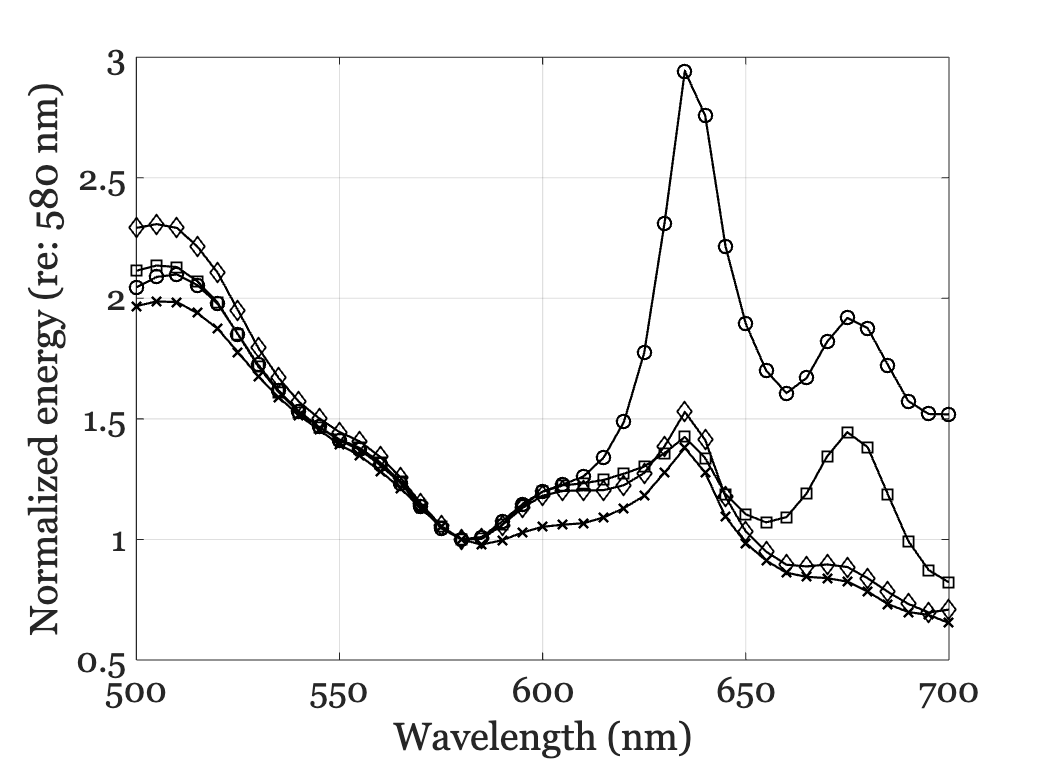

tongueFiles405 = ieTableGet(T,'ewave',405,'substrate','tongue','elevel',980,'return','files');

% Collected on the same day as above.
selected = [1,2,4,5];
tongueFiles405 = tongueFiles405(selected);

data = zeros(numel(waves),numel(tongueFiles405));
for ii=1:numel(tongueFiles405)
    data(:,ii) = ieReadSpectra(tongueFiles405(ii),waves);
    data(:,ii) = data(:,ii)/data((waves==580),ii);
end

symbols = {'ko-','kx-','ks-','kd-'};
ieFigure;
for ii= 1:numel(tongueFiles405)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
end
grid on;
xlabel('Wavelength (nm)')
ylabel('Normalized energy (re: 580 nm)');

## Tongue 415 (980 mA)

tongueFiles415 = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910,'return','files');

idx = find(waves==580);
data = zeros(numel(waves),numel(tongueFiles415));
for ii=1:numel(tongueFiles415)
    data(:,ii) = ieReadSpectra(tongueFiles415(ii),waves);
    data(:,ii) = data(:,ii)/data(idx,ii);
end

% Collected on the same day as above.
selected = [1,3,5,7];
tongueFiles415 = tongueFiles415(selected);
data = data(:,selected);

symbols = {'ko-','kx-','ks-','kd-'};
ieFigure;
for ii= 1:numel(tongueFiles415)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
end
grid on;
xlabel('Wavelength (nm)')
ylabel('Normalized energy (re: 580 nm)');

## Tongue 450 (870 mA)

tongueFiles450 = ieTableGet(T,'ewave',450,'substrate','tongue','elevel',870,'return','files');

idx = find(waves==580);
data = zeros(numel(waves),numel(tongueFiles450));
for ii=1:numel(tongueFiles450)
    data(:,ii) = ieReadSpectra(tongueFiles450(ii),waves);
    data(:,ii) = data(:,ii)/data(idx,ii);
end

% Collected on the same day as above.

symbols = {'ko-','kx-','ks-','kd-'};
ieFigure;
for ii= 1:numel(tongueFiles450)
    plot(waves,data(:,ii),symbols{ii}); hold on; 
end
grid on;
xlabel('Wavelength (nm)')
ylabel('Normalized energy (re: 580 nm)');

## tongue 415

B_tongue_415 = ieReadSpectra('spd-2024-03-19-B_415nm_lip_910mA.mat',waves);
D_tongue_415 = ieReadSpectra('spd-2024-03-19-D_415nm_tongue_910mA.mat',waves); 
Z_tongue_415 = ieReadSpectra('spd-2024-03-14-Z-415nm_Tongue_910mA.mat',waves);
J_tongue_415 = ieReadSpectra('spd-2024-03-12-11-415nm-J-tongue-910mA.mat',waves);

## tongue 450

B_tongue_450 = ieReadSpectra('spd-2024-03-19-B_450nm_tongue_870mA.mat',waves);
D_tongue_450 = ieReadSpectra('spd-2024-03-19-D_450nm_tongue_870mA.mat',waves);
Z_tongue_450 = ieReadSpectra('spd-2024-03-14-Z-450nm_tongue_870mA.mat',waves);;
J_tongue_450 = ieReadSpectra('spd-2024-03-12-450nm-J-tongue-460mA-1.mat',waves);

## lip 405

B_lip_405 = ieReadSpectra('spd-2024-03-19-B_405nm_lip_980mA.mat',waves);
D_lip_405 = ieReadSpectra('spd-2024-03-19-D_4050nm_lip_980mA.mat',waves);
Z_lip_405 = ieReadSpectra('spd-2024-03-14-Z-405nm_lip_980mA.mat',waves);
J_lip_405 = ieReadSpectra('spd-2024-03-12-11-405nm-J-lip-980mA.mat',waves);

## lip 415

B_lip_415 = ieReadSpectra('spd-2024-03-19-B_415nm_lip_910mA.mat',waves);
D_lip_415 = ieReadSpectra('spd-2024-03-19-D_415nm_lip_910mA.mat',waves);
Z_lip_415 = ieReadSpectra('spd-2024-03-14-Z-415nm_lip_910mA.mat',waves);
J_lip_415 = ieReadSpectra('spd-2024-03-12-11-415nm-J-lip-910mA.mat',waves);

## lip 450

B_lip_450 = ieReadSpectra('spd-2024-03-19-B_450nm_lip_870mA.mat',waves);
D_lip_450 = ieReadSpectra('spd-2024-03-19-D_450nm_lip_870mA.mat',waves);
Z_lip_450 = ieReadSpectra('spd-2024-03-14-Z-450nm_lip_870mA.mat',waves);
J_lip_450 = ieReadSpectra('spd-2024-03-12-11-450nm-J-lip-870mA.mat',waves);

## Plotting the normalized data

all should have ymin of 0 and ymax of 3.5 so we can compare scale?

figure; plot(waves,B_tongue_405/B_tongue_405(20),'k--x','LineWidth',1); hold on;
plot(waves,D_tongue_405/D_tongue_405(20),'k--*','LineWidth',1);
plot(waves,Z_tongue_405/Z_tongue_405(20),'k--^','LineWidth',1);
plot(waves,J_tongue_405/J_tongue_405(20),'k--o','LineWidth',1);
title("Dorsal tongue: 405 nm")
ylim([0 3.5]);
xlabel('Wavelength (nm)')
ylabel('Normalized Radiance'); % do we put arbitrary units?
fontsize(gca,14,"pixels");

figure; plot(waves,B_tongue_415/B_tongue_415(20),'k--x','LineWidth',1); hold on;
plot(waves,D_tongue_415/D_tongue_415(20),'k--*','LineWidth',1);
plot(waves,Z_tongue_415/Z_tongue_415(20),'k--^','LineWidth',1);
plot(waves,J_tongue_415/J_tongue_415(20),'k--o','LineWidth',1);
title("Dorsal tongue: 415 nm")
ylim([0 3.5]);
xlabel('Wavelength (nm)')
ylabel('Normalized Radiance'); % do we put arbitrary units?
fontsize(gca,14,"pixels");

figure; plot(waves,B_tongue_450/B_tongue_450(20),'k--x','LineWidth',1); hold on;
plot(waves,D_tongue_450/D_tongue_450(20),'k--*','LineWidth',1);
plot(waves,Z_tongue_450/Z_tongue_450(20),'k--^','LineWidth',1);
plot(waves,J_tongue_450/J_tongue_450(20),'k--o','LineWidth',1);
title("Dorsal tongue: 450 nm")
ylim([0 3.5]);
xlabel('Wavelength (nm)')
ylabel('Normalized Radiance'); % do we put arbitrary units?
fontsize(gca,14,"pixels");

figure; plot(waves,B_lip_405/B_lip_405(20),'k--x','LineWidth',1); hold on;
plot(waves,D_lip_405/D_lip_405(20),'k--*','LineWidth',1);
plot(waves,Z_lip_405/Z_lip_405(20),'k--^','LineWidth',1);
plot(waves,J_lip_405/J_lip_405(20),'k--o','LineWidth',1);
title("Inner lower lip: 405 nm")
ylim([0 3.5]);
xlabel('Wavelength (nm)')
ylabel('Normalized Radiance'); % do we put arbitrary units?
fontsize(gca,14,"pixels");

figure; plot(waves,B_lip_415/B_lip_415(20),'k--x','LineWidth',1); hold on;
plot(waves,D_lip_415/D_lip_415(20),'k--*','LineWidth',1);
plot(waves,Z_lip_415/Z_lip_415(20),'k--^','LineWidth',1);
plot(waves,J_lip_415/J_lip_415(20),'k--o','LineWidth',1);;
title("Inner lower lip: 415 nm")
ylim([0 3.5]);
xlabel('Wavelength (nm)')
ylabel('Normalized Radiance'); % do we put arbitrary units?
fontsize(gca,14,"pixels");

figure; plot(waves,B_lip_450/B_lip_450(20),'k--x','LineWidth',1);; hold on;
plot(waves,D_lip_450/D_lip_450(20),'k--*','LineWidth',1);
plot(waves,Z_lip_450/Z_lip_450(20),'k--^','LineWidth',1);
plot(waves,J_lip_450/J_lip_450(20),'k--o','LineWidth',1);
title("Inner lower lip: 450 nm")
ylim([0 3.5]);
xlabel('Wavelength (nm)')
ylabel('Normalized Radiance'); % do we put arbitrary units?
fontsize(gca,14,"pixels");